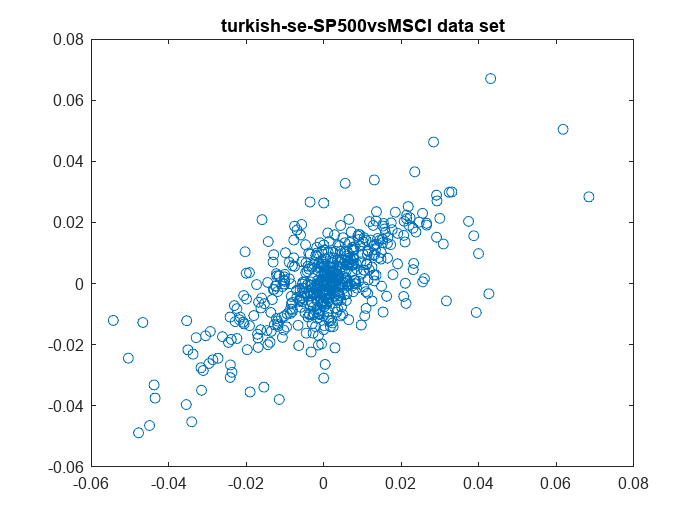

% Task 1
clear
clc

% Loading data
load 'mtcarsdata-4features.csv'
load 'turkish-se-SP500vsMSCI.csv'

% Data in matrices 
mtscar = mtcarsdata_4features;
turk = turkish_se_SP500vsMSCI;

% Task 2

% 2.1 One-dimensional problem without intercept on the Turkish stock exchange data

% Data plot of turkish-se-SP500vsMSCI data set
plot(turk(:,1), turk(:,2), 'o')
title('turkish-se-SP500vsMSCI data set')

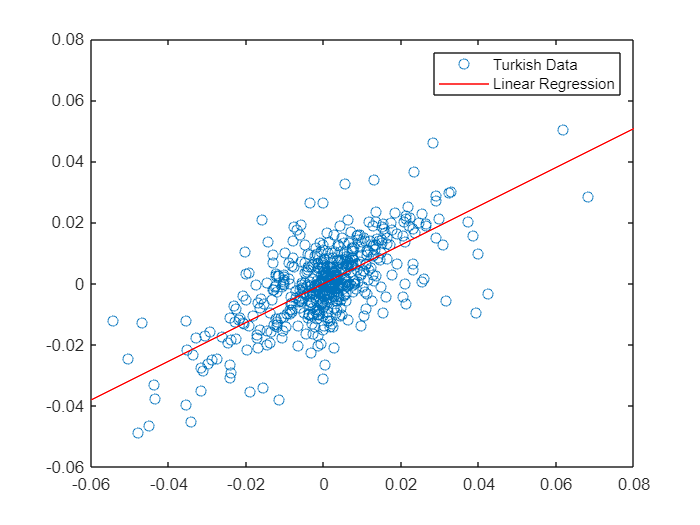


% Find w considering the whole turkish-se-SP500vsMSCI data set
firstColumn = turk(:, 1);
quadrati1 = firstColumn .^ 2;
sumQuadrati1 = sum(quadrati1);
denominator1 = sumQuadrati1;

result1 = [];
for row = 1:size(turk,1)
    product1 = turk(row, 1) * turk(row, 2);
    result1 = [result1; product1];
end

numerator1 = sum(result1);

w = numerator1/denominator1;
%disp("w: " + w)

% Plot
x = -0.06:0.01:0.08;
y = w*x;

figure;
plot(turk(:,1), turk(:,2), 'o')
hold on; 
plot(x, y, 'r');
legend('Turkish Data', 'Linear Regression');

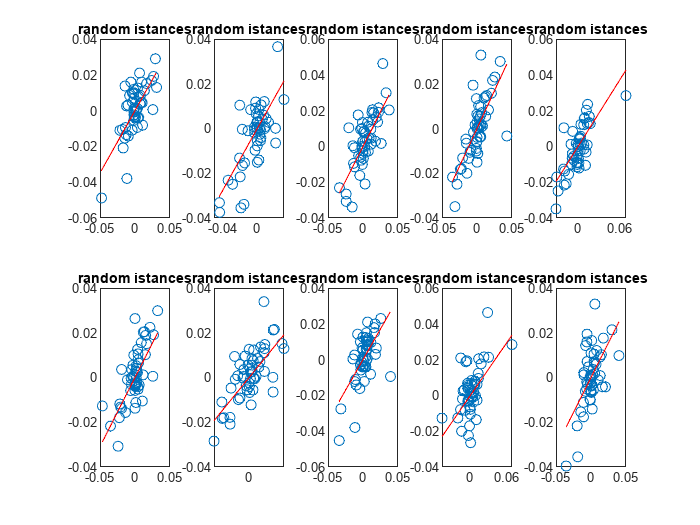



% 2.2 Compare graphically the solution obtained on different random subsets (10%) of the whole data set
% Creation of 10 subsets
n_subset = 10;
for i = 1:n_subset
    N = size(turk,1);
    allIndices = randperm(N); 
    m = 10/100 * N;
    randomSubset = allIndices(1:m); 
    subsets = turk(randomSubset,:);
    
     % TO SEE BETTER OPEN IN FIGURE WINDOW
    subplot(2,5,i); % creation of subplot
    plot(subsets(:,1), subsets(:,2), 'o'); hold on;
    
    
    % Find w
    firstColumn = subsets(:, 1);
    quadrati1 = firstColumn .^ 2;
    sumQuadrati1 = sum(quadrati1);
    denominator1 = sumQuadrati1;
    result1 = firstColumn .* subsets(:, 2);
    numerator1 = sum(result1);
    
    w = numerator1/denominator1;
    %disp("w: " + w)
    
    % Computation of the line
    x = linspace(min(subsets(:,1)), max(subsets(:,1)), 100);
    y = w * x;
    plot(x, y, 'r');
    title ("random istances")
end

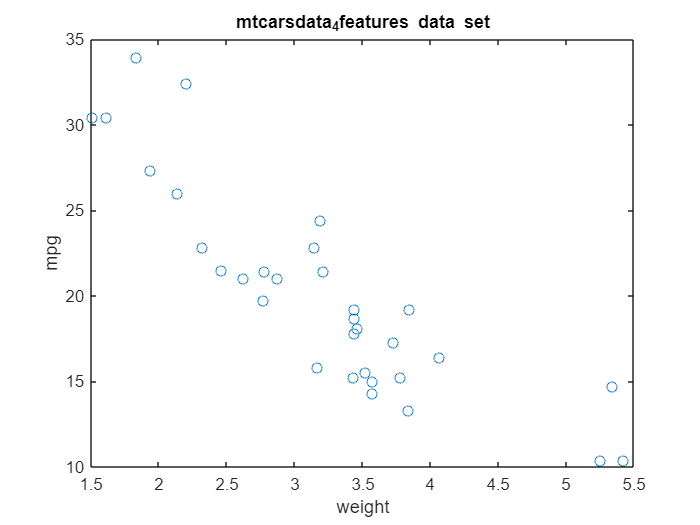




% 2.3 One-dimensional problem with intercept on the Motor Trends car data, using columns mpg and weight

% Data plot of mtcarsdata-4features data set
figure;
plot(mtscar(:,4), mtscar(:,1), 'o')
title('mtcarsdata_4features data set')
xlabel("weight")
ylabel("mpg")


 
% Find the mean of x (weight)

tmp1 = 0;
for i=1:size(mtscar,1)
    tmp1 = tmp1 + mtscar(i,4) ;
end

%disp(tmp1)

xmean = tmp1 / size(mtscar,1)

xmean = 3.2172


% Find the mean of t (mpg)

tmp2 = 0;
for i=1:size(mtscar,1)
    tmp2 = tmp2 + mtscar(i,1) ;
end

%disp(tmp2)

tmean = tmp2 / size(mtscar,1)

tmean = 20.0906

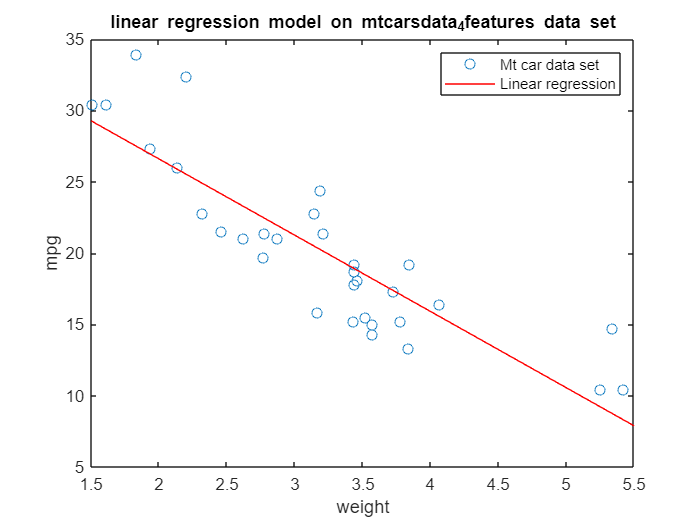



% Find w1

% Computation of each part of the formula:
vector1 = mtscar(:,4)-xmean;
vector2 = mtscar(:,1)-tmean;

vector12 = sum(vector1.*vector2);

quad = (vector1).^2;

vector3 = sum(quad);

w1 = vector12 / vector3;

% Find w0
w0 = tmean - w1*xmean;


% Line
x2 = 1.5:0.1:5.5;
y2 = w0 + x2*w1;

 % Plot
figure;
plot(mtscar(:,4), mtscar(:,1), 'o')
hold on;
plot(x2,y2,'r')
title("linear regression model on mtcarsdata_4features data set")
xlabel("weight")
ylabel("mpg")
legend('Mt car data set', 'Linear regression')



% 2.4 Multi-dimensional problem on the complete MTcars data, using all four columns (predict mpg with the other three columns)
Xm = [ones(size(mtscar,1),1), mtscar(: , 2:4)]; 
targ = mtscar(:,1);

% Moore-Penrose pseudo inverse 
w_multi = (pinv(Xm' * Xm)) * (Xm') * targ;
y_multi = Xm * w_multi;


disp("Values of w computed by Moore-Penrose pseudo-inverse formula:" )

Values of w computed by Moore-Penrose pseudo-inverse formula:


disp(+ w_multi) 

   37.1055
   -0.0009
   -0.0312
   -3.8009

